## Rozkład t-Studenta

Zmienna losowa Z ma rozkład normalny standaryzowany Z~N(0,1), $\chi^2$ - rozkład chi-kwadrat, k - liczba stopni swobody rozkładu.

Zmienna losowa utworzona jako:

$t=\frac{Z}{\sqrt{\chi^2 }}\sqrt{k}$ ,

ma rozkład t-Studenta z liczbą stopni swobody równą k.

Parametry rozkładu t-Studenta :

- wartość oczekiwana (średnia): $E\left(t\right)=0$, k>1

- wariancja: $D^2 \left(t\right)=\frac{k}{k-2}$, k>2

- odchylenie standardowe: $D\left(t\right)=\sqrt{\frac{k}{k-2}},\;k>2\ldotp$

Zobacz na program:

%disttool

## Rozkład gęstości prawdopodobieństwa (pdf) rozkłau t-Studenta

[tpdf](https://www.mathworks.com/help/releases/R2020a/stats/tpdf.html) - *Student's t probability density function*

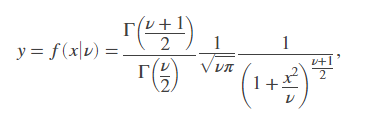

clear all; close all, clc, clearvars

t=[ -5:0.1:5 ]  %zakres zmiennej losowej

k1=2            %liczba stopni swobody
y=tpdf(t,k1)    %f. gęstości prowdopodobieństwa r. t-Student

figure(1)
grid on
hold on 
p=plot(t,y)    %wyrysowanie

p.LineWidth = 2;
p.LineStyle= '-';
p.Color='Black'


k1 = 2

k2=30          %liczba stopni swobody

k2 = 30

y2=tpdf(t,k2)  %f. gęstości prowdopodobieństwa r. t-Student

p2=plot(t,y2)
p2.LineWidth = 2;
p2.LineStyle= '-';
p2.Color='Red'


% plot(t,y,'Color','black','LineStyle','-','LineWidth',2)
% 
% plot(t,y2,'Color','red','LineStyle','-','LineWidth',2)

xlabel('Obserwacje')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')


Dokładamy rozkład Normalny

% mu=0
% sigma=1
% z=-5:0.01:5
% 
% pd=makedist('Normal','mu',mu,'sigma',sigma);
% pdf_normal = pdf(pd,z);

%lub
%Gauss

z=-5:0.1:5

z =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


y3 = normpdf(z)  %f. gęstości prowdopodobieństwa r. Normalnego

y3 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0012    0.0017    0.0024    0.0033    0.0044    0.0060    0.0079    0.0104    0.0136    0.0175    0.0224    0.0283    0.0355    0.0440    0.0540    0.0656    0.0790    0.0940    0.1109    0.1295    0.1497    0.1714    0.1942    0.2179    0.2420    0.2661    0.2897    0.3123    0.3332    0.3521    0.3683    0.3814    0.3910    0.3970


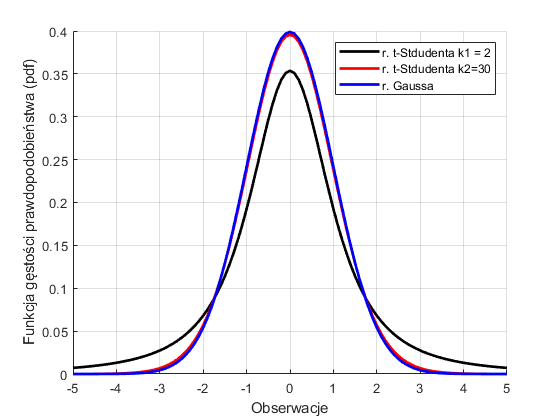


plot(z,y3,'Color','blue','LineStyle','-','LineWidth',2)
legend({'r. t-Stdudenta k1 = 2','r. t-Stdudenta k2=30','r. Gaussa'})

Do wizualizacji rozkładu normalnego można zastosować ogólną funkcje [pdf ](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.pdf.html) lub dedykowaną funkcję [ normpdf](https://www.mathworks.com/help/releases/R2020a/stats/normpdf.html).

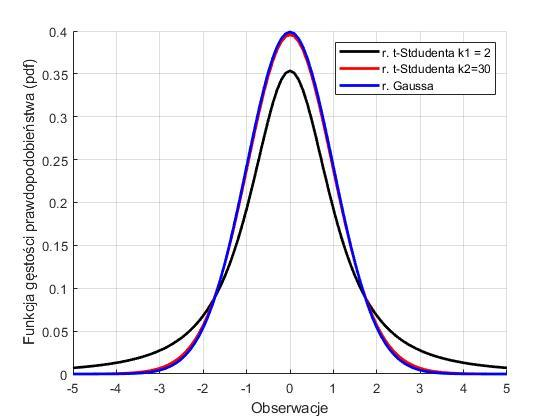

## Dystrybuanta rozkładu t-Studenta

[tcdf](https://www.mathworks.com/help/releases/R2020a/stats/tcdf.html) - *Student's t cumulative distribution function*

Przykład

- Oblicz prawdopodobieństwo, że zmienna losowa o rozkładzie t-Studenta z liczbą swobody równą 10 przyjmie wartości większe lub równe 1,4

             $P\left(t\ge 1,4\right)$.

t=1.4

t = 1.4000

k=10

k = 10

p = 1-tcdf(t,k)

p = 0.0959

p=tcdf(t,k,'upper') %inne użycie/wywołanie funkcji

p = 0.0959

- Oblicz prawdopodobieństwo, że zmienna losowa o rozkładzie t-Studenta z liczbą swobody równą 10 przyjmie wartości mniejsze lub równe -0,5

             $P\left(t\le -0,5\right)$.

t=-0.5

t = -0.5000

k=10

k = 10

p = tcdf(t,k)

p = 0.3139

**Odwrotność dystrybuanty rozkładu t-Sudenta**

[tinv](https://www.mathworks.com/help/releases/R2020a/stats/tinv.html) (*Student's t inverse cumulative distribution function*)

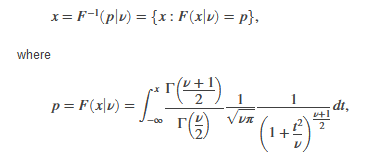

Przykład

- Znajdź wartość zmiennej x dla której

            $P\left(t\le x\right)$=0,3139 ?

p = 0.3139;   
k = 10;   
x = tinv(p,k)

t = -0.5001

- Znajdź wartość zmiennej x dla której

            $P\left(t\le x\right)$=0,95 ?

p = 0.95;   
k = 10;   
x = tinv(p,k)

t = 1.8125

- Znajdź górną i dolną granicę dla 95% przedziału ufności.

k=10;

k = 10

conf = 0.95;
alpha = 1 - conf;
pLo = alpha/2;
pUp = 1 - alpha/2;

Obliczenie granic przedziału ufności (r. t-Studenta):

tcrit = tinv([pLo pUp], k)

tcrit =    -2.2281    2.2281
